# Planificación y ejecucción de planificacion mediante interpolación

Generación de trayectorias en el espacio articular mediante interpolación desde una posición inicial (qi) y una posición final (qf).

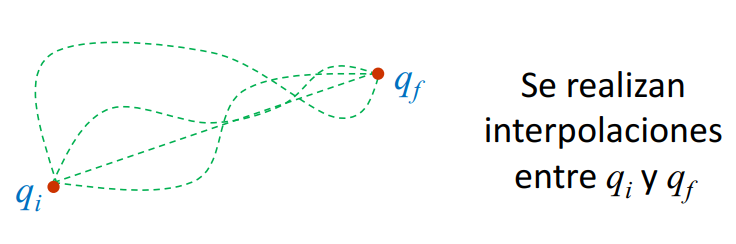

Especificaciones:

- Posición inicial y posición finalde cada articulación del robot

- Velocidad inicial y final de cada articulación del robot

- Aceleración inicial y final de cada articulacíon del robot

Ejemplos de interpolación:

- **Polinomios: cúbico, de quinto grado,** ..., etc.

- **Interpolación con velocidad trapezoidal**, trayectoria de tiempo mínimo, etc.

Generación de trayecotrias en el espacio articular pasando por una secuencia de puntos

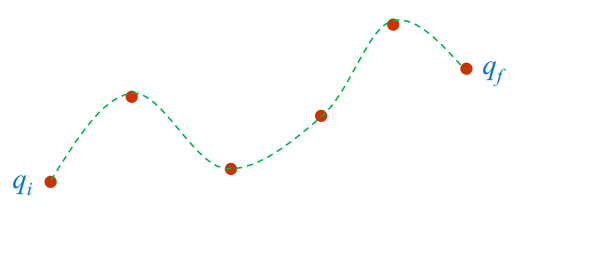

Interesa:

- Conocer los puntos intermedios entre qi y qf (definidos mediante interpolación entre el punto inicial y el punto final o especificaciones propias de la trayectoria)

- Que haya continuidad de velocidad/aceleración en los puntos intermedios

Usos: 

- Para evitar obstáculos 

- Para seguir trayectorias 'finas'

Métodos:

- Opción 1: Polinomios de grado alto (con N puntos, se requiere utilizar un polinomio de grado N-1)

- Opcion 2: Polinomios de bajo grado en cada segmento. Interpolación con **'splines' **permite generar una curva suave (continuidad hasta la 2º derivada) 

En este ejemplo se va a generar y simular trayectorias tanto en el espacio cartesiano y articular desde un punto inicial hasta un punto final. En el espacio articular se van a generar trayecotrias desde un punto inicial a un punto final utilizando interpolación cúbica, de 5 orden y velocidad trapezoidal. Para unir estos puntos se va a utilizar interpolación mediante splines para generar una curva suave.

clear 
close all
%load the ribig body tree robot model
robot = loadrobot('kinovaGen3','DataFormat','row','Gravity',[0 0 -9.81]);
%get home configuration of the robot
currentRobotJConfig = homeConfiguration(robot);
%number of joints of the robot
numJoints = numel(currentRobotJConfig);
endEffector = "EndEffector_Link";

Especificaciones de la trayectoria. El tiempo de la trayectoria se determina mediante la velocidad deseada del end-effector

timeStep = 0.1; % seconds
toolSpeed = 0.1; % m/s
jointInit = currentRobotJConfig; % initial pose 
taskInit = getTransform(robot,jointInit,endEffector);  
taskFinal = trvec2tform([0.4,0,0.6])*axang2tform([0 1 0 pi]);  %final pose

## Generación de trayectorias en el espacio por interpolación

Calculo de la trayectoria en el espacio cartesiano mediante la interpolación lineal del punto inicial y final dado un tiempo mediante la función [transformtraj](https://es.mathworks.com/help/robotics/ref/transformtraj.html?s_tid=srchtitle_transformtraj_1). 

%Calculo de la distancia de la trayectoria
distance = norm(tform2trvec(taskInit)-tform2trvec(taskFinal));
%Calculo de los tiempos de la trayectoria en función de la distancia a recorrer y la velocidad deseada
initTime = 0;
finalTime = (distance/toolSpeed) - initTime;
trajTimes = initTime:timeStep:finalTime;
timeInterval = [trajTimes(1); trajTimes(end)];
%Calculo de trayectoria en el espacio por interpolación de puntos
[taskWaypoints,taskVelocities] = transformtraj(taskInit,taskFinal,timeInterval,trajTimes); 

Crear el model de movimiento en el espacio cartesiano (solo se puede utilizar el control PD)

%Crear taskSpaceMotionModel del robot (control PD)
tsMotionModel = taskSpaceMotionModel('RigidBodyTree',robot,'EndEffectorName',endEffector);
%Fijar ganancia proporcional y derivativa de la orientación a cero, para que el comportamiento controlado solo siga las posiciones de referencia
MotionModel.Kp(1:3,1:3) = 0;
tsMotionModel.Kd(1:3,1:3) = 0;
%Definir los estados iniciales 
q0 = currentRobotJConfig;       %posición angular
qd0 = zeros(size(q0));          %velocidad angular

Usamos ode15 para la simulación del robot. Para este problema,  el integrador a veces se ve obligado a dar pasos extremadamente pequeños, y un solucionador de ODE no rígido como ode45 tardará mucho más en resolver el mismo problema. Para obtener más información, consulte [Choose an ODE Solver](docid:matlab_math#bu1mo3d-1) y [Solve Stiff ODEs](docid:matlab_math#bu22m86).

Dado que el estado de referencia cambia en cada instante, se requiere una función contenedora para actualizar la entrada de trayectoria interpolada a la derivada de estado en cada instante. Por lo tanto, se pasa una función auxiliar como identificador de función al solucionador de ODE. Los estados del manipulador resultantes se guardan en `stateTask`. 

[tTask,stateTask] = ode15s(@(t,state) derivativeTransfFormTraj(tsMotionModel,timeInterval,taskInit,taskFinal,t,state),timeInterval,[q0; qd0]);

## Generación de trayectorias en el espacio articular por interpolación

Creación del objeto inverseKinematics para el robot.

ik = inverseKinematics('RigidBodyTree',robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];
initialGuess = jointInit;
jointFinal = ik(endEffector,taskFinal,weights,initialGuess);

Por defecto, la solución está dentro de los límites de las articulaciones. Sin embargo, para articulaciones rotativas con rango infinitio, la solución puede ser excesivamente grande y pueden ajustarse dentro del limite `[-pi, pi]con la función wrapToPi.`

wrappedJointFinal = wrapToPi(jointFinal);

A partir de la configuración inicial y final, generamos trayectorias para cada una de las articulaciones utilizando la interpolación cúbica, de 5 orden y de velocidad trapezoidal. .

%angulos iniciales, angulos finales
ctrlpoints = [jointInit',wrappedJointFinal'];
%gpolinómica de 3º orden
[jointConfigCubic, jointVelocCubic, jointAccelCubic] = cubicpolytraj(ctrlpoints,timeInterval,trajTimes);    
%polinómica de 5 orden
[jointConfigQuintic, jointVelocQuintic, jointAccelQuintic] = quinticpolytraj(ctrlpoints,timeInterval,trajTimes);  
%trapezoidal velocity
[jointConfigTrapez, jointVelocTrapez, jointAccelTrapez] = trapveltraj(ctrlpoints,length (trajTimes));  

Creación del movimiento en el espacio articular, utilizando un control PD. Usamos una interpolación B-spline para generar una trayectoria suave.

%Modelo de movimeinto en el espacio de articulaciones %(control PD)
jsMotionModel = jointSpaceMotionModel('RigidBodyTree',robot,'MotionType','PDControl');
%Definición de estado inicial 
q0 = currentRobotJConfig;       %posición articular
qd0 = zeros(size(q0));          %velocidad raticular
%Usamos ode15s para simular el movimiento del robot. 
%Se utiliza una función auxiliar como entrada al solucionador ODE para actualizar las entradas en cada instante de tiempo. 
[tJoint_3,stateJoint_3] = ode15s(@(t,state) derivativeBSpline(jsMotionModel,timeInterval,jointConfigCubic,t,state),timeInterval,[q0; qd0]);
[tJoint_5,stateJoint_5] = ode15s(@(t,state) derivativeBSpline(jsMotionModel,timeInterval,jointConfigQuintic,t,state),timeInterval,[q0; qd0]);
[tJoint_trap,stateJoint_trap] = ode15s(@(t,state) derivativeBSpline(jsMotionModel,timeInterval,jointConfigTrapez,t,state),timeInterval,[q0; qd0]);

## GRAFICAR

- **INTERPOLACIÓN CÚBICA**

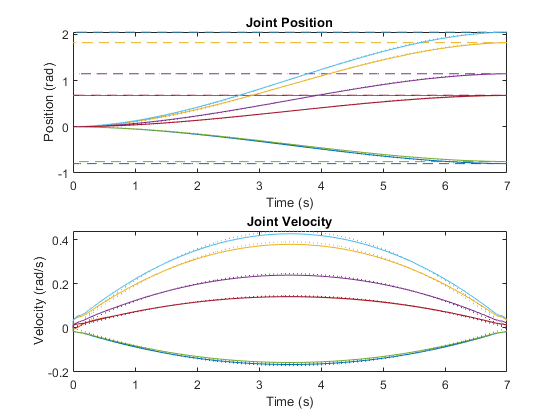

plotJointPositionSpeed2 (tJoint_3, stateJoint_3, trajTimes, [jointConfigCubic; jointVelocCubic]',  wrappedJointFinal', numJoints);

- **INTERPOLACIÓN DE 5 ORDEN**

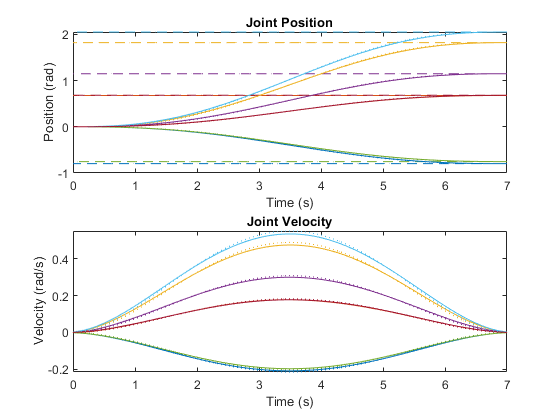

plotJointPositionSpeed2 (tJoint_5, stateJoint_5, trajTimes, [jointConfigQuintic; jointVelocQuintic]', wrappedJointFinal', numJoints);

- **INTERPOLACIÓN TRAPEZOIDAL**

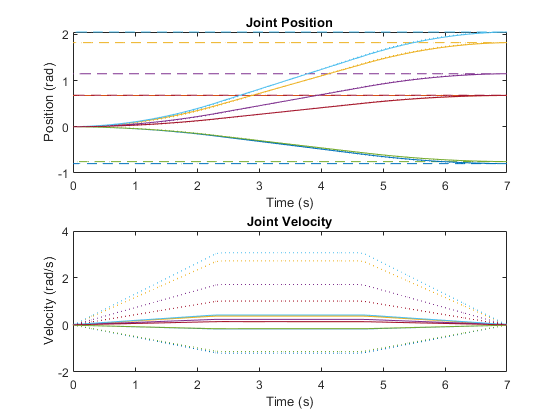

plotJointPositionSpeed2 (tJoint_trap, stateJoint_trap, trajTimes, [jointConfigTrapez; jointVelocTrapez]',  wrappedJointFinal', numJoints);

## Visualización de las trayectorias seguidas por el robot

Creamos la figura y mostramos la configuración inicial del robot.

figure
set(gcf,'Visible','on')
show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');
hold on
axis([-1 1 -1 1 -0.1 1.5]);

Visualizamos la trayectoria generada en el espacio cartesiano. Iterar sobre el `stateTask` states e interpolar.

for i=1:length(trajTimes)
    % Current time 
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time
    configNow = interp1(tTask,stateTask(:,1:numJoints),tNow);
    poseNow = getTransform(robot,configNow,endEffector);
    show(robot,configNow,'PreservePlot',false,'Frames','off');
    taskSpaceMarker = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'b.','MarkerSize',10);
    drawnow;
end

Visualizamos la trayectoria generada en el espacio articular utilizando la interpolación cúbica. 

% Return to initial configuration
show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');

for i=1:length(trajTimes)
    % Current time 
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time
    configNow = interp1(tJoint_3,stateJoint_3(:,1:numJoints),tNow);
    poseNow = getTransform(robot,configNow,endEffector);
    show(robot,configNow,'PreservePlot',false,'Frames','off');
    jointSpaceMarker = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',10);
    drawnow;
end

Visualizamos la trayectoria generada en el espacio articular utilizando la interpolación de orden 5. 

% Return to initial configuration
show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');

for i=1:length(trajTimes)
    % Current time 
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time
    configNow = interp1(tJoint_5,stateJoint_5(:,1:numJoints),tNow);
    poseNow = getTransform(robot,configNow,endEffector);
    show(robot,configNow,'PreservePlot',false,'Frames','off');
    jointSpaceMarker2 = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'g.','MarkerSize',10);
    drawnow;
end

Visualizamos la trayectoria generada en el espacio articular utilizando la interpolación trapezoidal de velocidad.

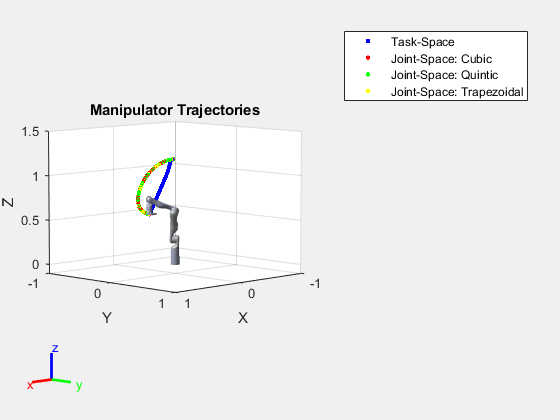

% Return to initial configuration
show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');

for i=1:length(trajTimes)
    % Current time 
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time
    configNow = interp1(tJoint_trap,stateJoint_trap(:,1:numJoints),tNow);
    poseNow = getTransform(robot,configNow,endEffector);
    show(robot,configNow,'PreservePlot',false,'Frames','off');
    jointSpaceMarker3 = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'y.','MarkerSize',10);
    drawnow;
end


legend([taskSpaceMarker jointSpaceMarker jointSpaceMarker2 jointSpaceMarker3], {'Task-Space', 'Joint-Space: Cubic',  'Joint-Space: Quintic', 'Joint-Space: Trapezoidal'});
title('Manipulator Trajectories')

## Visualización y comparacio de las trayectorias seguidas en el espacio articular

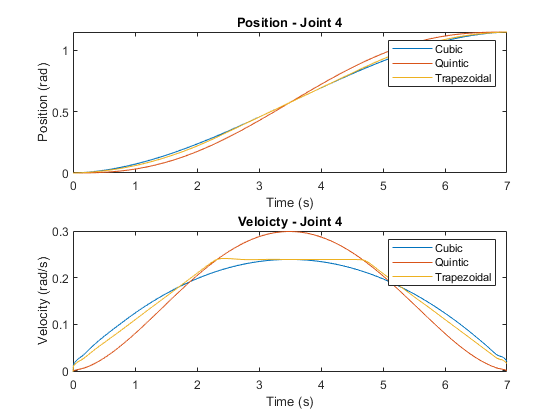

%Select joint to plot
joint = 4;
figure
subplot(2,1,1)
plot(tJoint_3,stateJoint_3(:,joint)) % Joint position
hold all
plot(tJoint_5,stateJoint_5(:,joint)) % Joint position
plot(tJoint_trap,stateJoint_trap(:,joint)) % Joint position
legend ('Cubic', 'Quintic', 'Trapezoidal')
title(append ('Position - Joint ', int2str (joint)))
xlabel('Time (s)')
ylabel('Position (rad)')
subplot(2,1,2)
plot(tJoint_3,stateJoint_3(:,joint+numJoints)) % Joint velocity
hold all
plot(tJoint_5,stateJoint_5(:,joint+numJoints)) % Joint velocity
plot(tJoint_trap,stateJoint_trap(:,joint+numJoints)) % Joint velocity
legend ('Cubic', 'Quintic', 'Trapezoidal')
title(append ('Veloicty - Joint ', int2str (joint)))
xlabel('Time (s)')
ylabel('Velocity (rad/s)')